**Part III : Autoregressive model**

clear
load hw3_3.mat

y= displacement(:,2);
time= displacement(:,1);

% AR(5) Model:
order=5;
Mdl= arima(order,0,0);
EstMdl = estimate(Mdl,y(1:81));

 
    ARIMA(5,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0084379       0.016523       -0.51069        0.60957
    AR{1}          0.52783        0.11849         4.4548     8.3976e-06
    AR{2}         0.097503        0.13631        0.71532        0.47441
    AR{3}        -0.095204        0.17144       -0.55532        0.57868
    AR{4}         -0.10412        0.14563       -0.71496        0.47463
    AR{5}         -0.27807        0.12547        -2.2162       0.026676
    Variance      0.017584      0.0035426         4.9636     6.9202e-07



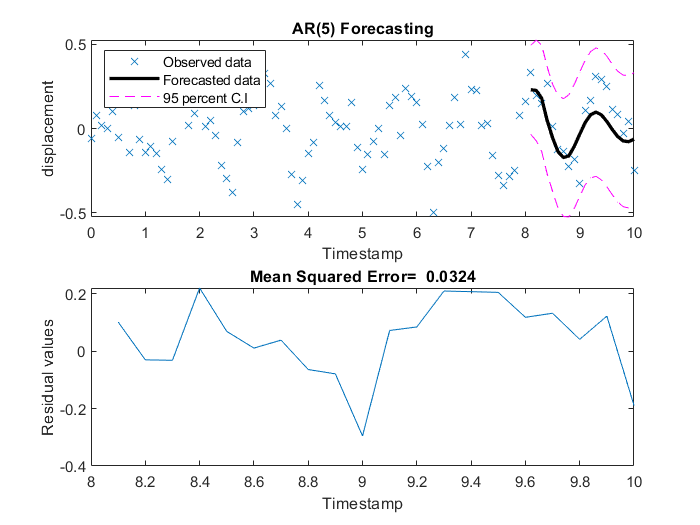

[Y,YMSE] = forecast(EstMdl,20,y(1:81));
figure
subplot(2,1,1)
plot(time, y,'x');hold on;
plot([8.1:0.1:10],Y,'k','LineWidth',2);
plot([8.1:0.1:10],Y+2*YMSE.^0.5,'m--',[8.1:0.1:10],Y-2*YMSE.^0.5,'m--');
title('AR(5) Forecasting'), xlabel('Timestamp'), ylabel('displacement'), legend({'Observed data','Forecasted data','95 percent C.I'},'Location','northwest');
hold off
subplot(2,1,2)
Residual= y(82:101)-Y;
plot([8.1:0.1:10],Residual)
MSE = mean(YMSE); header= sprintf("Mean Squared Error=  %.4f", MSE); 
title(header), xlabel('Timestamp'), ylabel('Residual values');

a) See above.** MSE= 0.0324**

% AR(10) Model:
clear
load hw3_3.mat

y= displacement(:,2);
time= displacement(:,1);
order=10;
Mdl= arima(order,0,0);
EstMdl = estimate(Mdl,y(1:81));

 
    ARIMA(10,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.021082       0.016457         -1.281        0.20018
    AR{1}         0.24929        0.12751         1.9551       0.050574
    AR{2}       -0.045623        0.14478       -0.31512        0.75267
    AR{3}        -0.22532        0.15358        -1.4671        0.14235
    AR{4}        -0.17653        0.13418        -1.3156         0.1883
    AR{5}        -0.16472        0.13804        -1.1933        0.23277
    AR{6}        -0.28952        0.10689        -2.7087      0.0067543
    AR{7}         -0.1765        0.

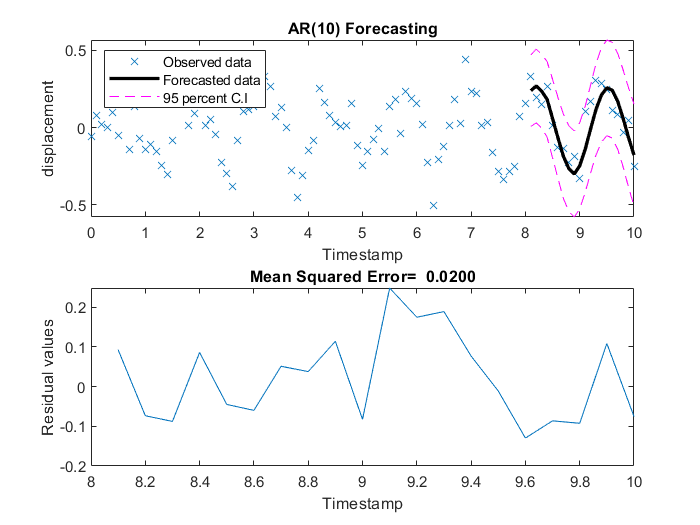

[Y,YMSE] = forecast(EstMdl,20,y(1:81));
figure
subplot(2,1,1)
plot(time, y,'x');hold on;
plot([8.1:0.1:10],Y,'k','LineWidth',2);
plot([8.1:0.1:10],Y+2*YMSE.^0.5,'m--',[8.1:0.1:10],Y-2*YMSE.^0.5,'m--');
title('AR(10) Forecasting'), xlabel('Timestamp'), ylabel('displacement'), legend({'Observed data','Forecasted data','95 percent C.I'},'Location','northwest');
hold off
subplot(2,1,2)
Residual= y(82:101)-Y;
plot([8.1:0.1:10],Residual)
MSE = mean(YMSE); header= sprintf("Mean Squared Error=  %.4f", MSE); 
title(header), xlabel('Timestamp'), ylabel('Residual values');

b) AR(10) forecasting seems to fit the observed data much better than AR(5) as can be inspected visually and corroborated by the lower **MSE=0.020**. AR(10) therefore provides a better prediction- also because of the fact that each forecasted value is estimated using the regression fit of last 10 values compared to AR(5) that uses last 5 values.

clear
load hw3_1.mat
pm2d5 = data.pm2d5;
time = data.time;
time_second = (datenum(time)-floor(datenum(time)))*24*60*60;

% AR(10) Model:
order=10;
Mdl= arima(order,0,0);
EstMdl = estimate(Mdl,pm2d5(1:1200));

 
    ARIMA(10,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.73578       0.35684          2.062         0.039211
    AR{1}        0.19845      0.023467         8.4564       2.7564e-17
    AR{2}        0.10403      0.028445         3.6571       0.00025507
    AR{3}        0.10943      0.031437         3.4809       0.00049982
    AR{4}        0.10402      0.031022         3.3531       0.00079916
    AR{5}       0.040042      0.030008         1.3344          0.18207
    AR{6}       0.094724       0.03027         3.1293        0.0017524
    AR{7}       0.092292      0.028

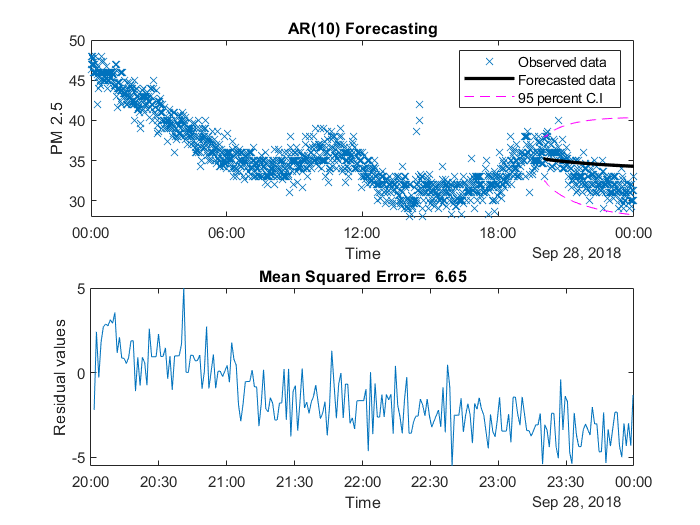

[Y,YMSE] = forecast(EstMdl,238,pm2d5(1:1200));

figure
subplot(2,1,1)
plot(time, pm2d5,'x');hold on;
plot(time(1201:end),Y,'k','LineWidth',2);
plot(time(1201:end),Y+2*YMSE.^0.5,'m--',time(1201:end),Y-2*YMSE.^0.5,'m--');
title('AR(10) Forecasting'), xlabel('Time'), ylabel('PM 2.5'), legend({'Observed data','Forecasted data','95 percent C.I'},'Location','northeast');
hold off
subplot(2,1,2)
Residual= pm2d5(1201:end)-Y;
plot(time(1201:end),Residual)
MSE = mean(YMSE); header= sprintf("Mean Squared Error=  %.2f", MSE); 
title(header), xlabel('Time'), ylabel('Residual values');

% AR(30) Model:
order=30;
Mdl= arima(order,0,0);
EstMdl = estimate(Mdl,pm2d5(1:1200));

 
    ARIMA(30,0,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic       PValue  
                ___________    _____________    ___________    __________

    Constant        0.71739       0.33396            2.1481      0.031703
    AR{1}           0.18226      0.025037            7.2797    3.3447e-13
    AR{2}          0.082829      0.030968            2.6747     0.0074804
    AR{3}          0.082057      0.032402            2.5324      0.011328
    AR{4}          0.080243      0.033013            2.4307      0.015071
    AR{5}          0.012776      0.033057           0.38647       0.69915
    AR{6}          0.069641      0.031311            2.2241       0.02614
    AR{7}   

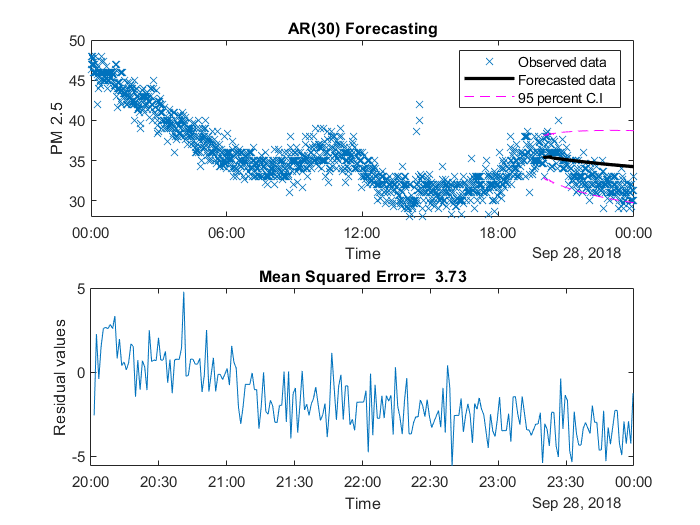

[Y,YMSE] = forecast(EstMdl,238,pm2d5(1:1200));

figure
subplot(2,1,1)
plot(time, pm2d5,'x');hold on;
plot(time(1201:end),Y,'k','LineWidth',2);
plot(time(1201:end),Y+2*YMSE.^0.5,'m--',time(1201:end),Y-2*YMSE.^0.5,'m--');
title('AR(30) Forecasting'), xlabel('Time'), ylabel('PM 2.5'), legend({'Observed data','Forecasted data','95 percent C.I'},'Location','northeast');
hold off
subplot(2,1,2)
Residual= pm2d5(1201:end)-Y;
plot(time(1201:end),Residual)
MSE = mean(YMSE); header= sprintf("Mean Squared Error=  %.2f", MSE); 
title(header), xlabel('Time'), ylabel('Residual values');

c) As seen from the AR(10) and AR(30) plots above and their corresponding residual plots, the forecasted PM 2.5 values seem to severely underperform/underfit compared to harmonic displacement vaues in part b). This conclusion made from visual inspection of the plots is confirmed by the high MSE values of 6.65 for AR(10) and 3.73 for AR(30). I don't think increasing the order of AR model would help on improving the prediction performance because the result of increasing model order from 10 to 30 did very little to improve the prediction accuracy as can be seen visually and through MSE scores. There seems to be a diminishing return of MSE from increasing the model order. Therefore, I do not think that AR model is suitable for predicting PM 2.5 - most likley because of the fact that there are too many environmental features that affect the PM 2.5 levels and AR seems to work the best with low feature data.